a0=0;
a1=0;
a2=0;
a3=1;
z=zeros(80,1);%初始化伪随机序列
z(1)=a0;
z(2)=a1;
z(3)=a2;
z(4)=a3;
for i=1:76
    z(i+4)=(2.*z(i+1)+z(i+0));%进行迭代
    %按模3加法运算计算输出序列
    if  z(i+4)<=2
        z(i+4)=z(i+4);
    end
    if  z(i+4)>2
        z(i+4)=mod(z(i+4),3);
    end
end
B = reshape(z.',1,[]);%对伪随机序列进行维度变换


M=zeros(5,16)%生成相应大小的零矩阵

M =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


[r,c]=size(M)%提取M矩阵的行数和列数

r = 5

c = 16

R=[1:r]

R =      1     2     3     4     5


C=[1:c]

C =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16


for i=1:80
    %m表示填充的行数，n表示填充的列数
    %按对角线法填充，即m按总行数进行循环，n按总列数进行循环
    m=mod(i,r)
    if m==0
        m=r
    end
    
    n=mod(i,c)
    if n==0
        n=c
    end
    M(m,n)=B(i)%将伪随机序列B中的值填充至M阵列中   
end

m = 1

n = 1

M =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


m = 2

n = 2

M =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


m = 3

n = 3

M =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


m = 4

n = 4

M =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


m = 0

m = 5

n = 5

M =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


m = 1

n = 6

M =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


m = 2

n = 7

M =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     2     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


m = 3

n = 8

M =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     2     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


m = 4

n = 9

M =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     2     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


m = 0

m = 5

n = 10

M =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     2     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0


m = 1

n = 11

M =      0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0
     0     0     0     0     0     0     2     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0


m = 2

n = 12

M =      0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0
     0     0     0     0     0     0     2     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0


m = 3

n = 13

M =      0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0
     0     0     0     0     0     0     2     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     0     1     0     0     0     0     2     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0


m = 4

n = 14

M =      0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0
     0     0     0     0     0     0     2     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     0     1     0     0     0     0     2     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0


m = 0

m = 5

n = 15

M =      0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0
     0     0     0     0     0     0     2     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     0     1     0     0     0     0     2     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0


m = 1

n = 0

n = 16

M =      0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     2
     0     0     0     0     0     0     2     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     0     1     0     0     0     0     2     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0


m = 2

n = 1

M =      0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     2
     2     0     0     0     0     0     2     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     0     1     0     0     0     0     2     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0


m = 3

n = 2

M =      0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     2
     2     0     0     0     0     0     2     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     0     1     0     0     0     0     2     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0


m = 4

n = 3

M =      0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     2
     2     0     0     0     0     0     2     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     0     1     0     0     0     0     2     0     0     0
     0     0     1     1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0


m = 0

m = 5

n = 4

M =      0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     2
     2     0     0     0     0     0     2     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     0     1     0     0     0     0     2     0     0     0
     0     0     1     1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0


m = 1

n = 5

M =      0     0     0     0     2     0     0     0     0     0     1     0     0     0     0     2
     2     0     0     0     0     0     2     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     0     1     0     0     0     0     2     0     0     0
     0     0     1     1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0


m = 2

n = 6

M =      0     0     0     0     2     0     0     0     0     0     1     0     0     0     0     2
     2     0     0     0     0     2     2     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     0     1     0     0     0     0     2     0     0     0
     0     0     1     1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0


m = 3

n = 7

M =      0     0     0     0     2     0     0     0     0     0     1     0     0     0     0     2
     2     0     0     0     0     2     2     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     1     1     0     0     0     0     2     0     0     0
     0     0     1     1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0


m = 4

n = 8

M =      0     0     0     0     2     0     0     0     0     0     1     0     0     0     0     2
     2     0     0     0     0     2     2     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     1     1     0     0     0     0     2     0     0     0
     0     0     1     1     0     0     0     1     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0


m = 0

m = 5

n = 9

M =      0     0     0     0     2     0     0     0     0     0     1     0     0     0     0     2
     2     0     0     0     0     2     2     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     1     1     0     0     0     0     2     0     0     0
     0     0     1     1     0     0     0     1     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0


m = 1

n = 10

M =      0     0     0     0     2     0     0     0     0     1     1     0     0     0     0     2
     2     0     0     0     0     2     2     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     1     1     0     0     0     0     2     0     0     0
     0     0     1     1     0     0     0     1     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0


m = 2

n = 11

M =      0     0     0     0     2     0     0     0     0     1     1     0     0     0     0     2
     2     0     0     0     0     2     2     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     1     1     0     0     0     0     2     0     0     0
     0     0     1     1     0     0     0     1     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0


m = 3

n = 12

M =      0     0     0     0     2     0     0     0     0     1     1     0     0     0     0     2
     2     0     0     0     0     2     2     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     1     1     0     0     0     1     2     0     0     0
     0     0     1     1     0     0     0     1     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0


m = 4

n = 13

M =      0     0     0     0     2     0     0     0     0     1     1     0     0     0     0     2
     2     0     0     0     0     2     2     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     1     1     0     0     0     1     2     0     0     0
     0     0     1     1     0     0     0     1     0     0     0     0     2     0     0     0
     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0


m = 0

m = 5

n = 14

M =      0     0     0     0     2     0     0     0     0     1     1     0     0     0     0     2
     2     0     0     0     0     2     2     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     1     1     0     0     0     1     2     0     0     0
     0     0     1     1     0     0     0     1     0     0     0     0     2     0     0     0
     0     0     0     0     0     0     0     0     0     1     0     0     0     1     0     0


m = 1

n = 15

M =      0     0     0     0     2     0     0     0     0     1     1     0     0     0     2     2
     2     0     0     0     0     2     2     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     1     1     0     0     0     1     2     0     0     0
     0     0     1     1     0     0     0     1     0     0     0     0     2     0     0     0
     0     0     0     0     0     0     0     0     0     1     0     0     0     1     0     0


m = 2

n = 0

n = 16

M =      0     0     0     0     2     0     0     0     0     1     1     0     0     0     2     2
     2     0     0     0     0     2     2     0     0     0     0     1     0     0     0     2
     0     0     0     0     0     0     1     1     0     0     0     1     2     0     0     0
     0     0     1     1     0     0     0     1     0     0     0     0     2     0     0     0
     0     0     0     0     0     0     0     0     0     1     0     0     0     1     0     0


m = 3

n = 1

M =      0     0     0     0     2     0     0     0     0     1     1     0     0     0     2     2
     2     0     0     0     0     2     2     0     0     0     0     1     0     0     0     2
     1     0     0     0     0     0     1     1     0     0     0     1     2     0     0     0
     0     0     1     1     0     0     0     1     0     0     0     0     2     0     0     0
     0     0     0     0     0     0     0     0     0     1     0     0     0     1     0     0


m = 4

n = 2

M =      0     0     0     0     2     0     0     0     0     1     1     0     0     0     2     2
     2     0     0     0     0     2     2     0     0     0     0     1     0     0     0     2
     1     0     0     0     0     0     1     1     0     0     0     1     2     0     0     0
     0     2     1     1     0     0     0     1     0     0     0     0     2     0     0     0
     0     0     0     0     0     0     0     0     0     1     0     0     0     1     0     0


m = 0

m = 5

n = 3

M =      0     0     0     0     2     0     0     0     0     1     1     0     0     0     2     2
     2     0     0     0     0     2     2     0     0     0     0     1     0     0     0     2
     1     0     0     0     0     0     1     1     0     0     0     1     2     0     0     0
     0     2     1     1     0     0     0     1     0     0     0     0     2     0     0     0
     0     0     0     0     0     0     0     0     0     1     0     0     0     1     0     0


m = 1

n = 4

M =      0     0     0     1     2     0     0     0     0     1     1     0     0     0     2     2
     2     0     0     0     0     2     2     0     0     0     0     1     0     0     0     2
     1     0     0     0     0     0     1     1     0     0     0     1     2     0     0     0
     0     2     1     1     0     0     0     1     0     0     0     0     2     0     0     0
     0     0     0     0     0     0     0     0     0     1     0     0     0     1     0     0


m = 2

n = 5

M =      0     0     0     1     2     0     0     0     0     1     1     0     0     0     2     2
     2     0     0     0     2     2     2     0     0     0     0     1     0     0     0     2
     1     0     0     0     0     0     1     1     0     0     0     1     2     0     0     0
     0     2     1     1     0     0     0     1     0     0     0     0     2     0     0     0
     0     0     0     0     0     0     0     0     0     1     0     0     0     1     0     0


m = 3

n = 6

M =      0     0     0     1     2     0     0     0     0     1     1     0     0     0     2     2
     2     0     0     0     2     2     2     0     0     0     0     1     0     0     0     2
     1     0     0     0     0     2     1     1     0     0     0     1     2     0     0     0
     0     2     1     1     0     0     0     1     0     0     0     0     2     0     0     0
     0     0     0     0     0     0     0     0     0     1     0     0     0     1     0     0


m = 4

n = 7

M =      0     0     0     1     2     0     0     0     0     1     1     0     0     0     2     2
     2     0     0     0     2     2     2     0     0     0     0     1     0     0     0     2
     1     0     0     0     0     2     1     1     0     0     0     1     2     0     0     0
     0     2     1     1     0     0     2     1     0     0     0     0     2     0     0     0
     0     0     0     0     0     0     0     0     0     1     0     0     0     1     0     0


m = 0

m = 5

n = 8

M =      0     0     0     1     2     0     0     0     0     1     1     0     0     0     2     2
     2     0     0     0     2     2     2     0     0     0     0     1     0     0     0     2
     1     0     0     0     0     2     1     1     0     0     0     1     2     0     0     0
     0     2     1     1     0     0     2     1     0     0     0     0     2     0     0     0
     0     0     0     0     0     0     0     2     0     1     0     0     0     1     0     0


m = 1

n = 9

M =      0     0     0     1     2     0     0     0     0     1     1     0     0     0     2     2
     2     0     0     0     2     2     2     0     0     0     0     1     0     0     0     2
     1     0     0     0     0     2     1     1     0     0     0     1     2     0     0     0
     0     2     1     1     0     0     2     1     0     0     0     0     2     0     0     0
     0     0     0     0     0     0     0     2     0     1     0     0     0     1     0     0


m = 2

n = 10

M =      0     0     0     1     2     0     0     0     0     1     1     0     0     0     2     2
     2     0     0     0     2     2     2     0     0     0     0     1     0     0     0     2
     1     0     0     0     0     2     1     1     0     0     0     1     2     0     0     0
     0     2     1     1     0     0     2     1     0     0     0     0     2     0     0     0
     0     0     0     0     0     0     0     2     0     1     0     0     0     1     0     0


m = 3

n = 11

M =      0     0     0     1     2     0     0     0     0     1     1     0     0     0     2     2
     2     0     0     0     2     2     2     0     0     0     0     1     0     0     0     2
     1     0     0     0     0     2     1     1     0     0     0     1     2     0     0     0
     0     2     1     1     0     0     2     1     0     0     0     0     2     0     0     0
     0     0     0     0     0     0     0     2     0     1     0     0     0     1     0     0


m = 4

n = 12

M =      0     0     0     1     2     0     0     0     0     1     1     0     0     0     2     2
     2     0     0     0     2     2     2     0     0     0     0     1     0     0     0     2
     1     0     0     0     0     2     1     1     0     0     0     1     2     0     0     0
     0     2     1     1     0     0     2     1     0     0     0     2     2     0     0     0
     0     0     0     0     0     0     0     2     0     1     0     0     0     1     0     0


m = 0

m = 5

n = 13

M =      0     0     0     1     2     0     0     0     0     1     1     0     0     0     2     2
     2     0     0     0     2     2     2     0     0     0     0     1     0     0     0     2
     1     0     0     0     0     2     1     1     0     0     0     1     2     0     0     0
     0     2     1     1     0     0     2     1     0     0     0     2     2     0     0     0
     0     0     0     0     0     0     0     2     0     1     0     0     0     1     0     0


m = 1

n = 14

M =      0     0     0     1     2     0     0     0     0     1     1     0     0     0     2     2
     2     0     0     0     2     2     2     0     0     0     0     1     0     0     0     2
     1     0     0     0     0     2     1     1     0     0     0     1     2     0     0     0
     0     2     1     1     0     0     2     1     0     0     0     2     2     0     0     0
     0     0     0     0     0     0     0     2     0     1     0     0     0     1     0     0


m = 2

n = 15

M =      0     0     0     1     2     0     0     0     0     1     1     0     0     0     2     2
     2     0     0     0     2     2     2     0     0     0     0     1     0     0     1     2
     1     0     0     0     0     2     1     1     0     0     0     1     2     0     0     0
     0     2     1     1     0     0     2     1     0     0     0     2     2     0     0     0
     0     0     0     0     0     0     0     2     0     1     0     0     0     1     0     0


m = 3

n = 0

n = 16

M = 5×16
     0     0     0     1     2     0     0     0     0     1     1     0     0     0     2     2
     2     0     0     0     2     2     2     0     0     0     0     1     0     0     1     2
     1     0     0     0     0     2     1     1     0     0     0     1     2     0     0     2
     0     2     1     1     0     0     2     1     0     0     0     2     2     0     0     0
     0     0     0     0     0     0     0     2     0     1     0     0     0     1     0     0


m = 4

n = 1

M = 5×16
     0     0     0     1     2     0     0     0     0     1     1     0     0     0     2     2
     2     0     0     0     2     2     2     0     0     0     0     1     0     0     1     2
     1     0     0     0     0     2     1     1     0     0     0     1     2     0     0     2
     0     2     1     1     0     0     2     1     0     0     0     2     2     0     0     0
     0     0     0     0     0     0     0     2     0     1     0     0     0     1     0     0


m = 0

m = 5

n = 2

M = 5×16
     0     0     0     1     2     0     0     0     0     1     1     0     0     0     2     2
     2     0     0     0     2     2     2     0     0     0     0     1     0     0     1     2
     1     0     0     0     0     2     1     1     0     0     0     1     2     0     0     2
     0     2     1     1     0     0     2     1     0     0     0     2     2     0     0     0
     0     2     0     0     0     0     0     2     0     1     0     0     0     1     0     0


m = 1

n = 3

M = 5×16
     0     0     2     1     2     0     0     0     0     1     1     0     0     0     2     2
     2     0     0     0     2     2     2     0     0     0     0     1     0     0     1     2
     1     0     0     0     0     2     1     1     0     0     0     1     2     0     0     2
     0     2     1     1     0     0     2     1     0     0     0     2     2     0     0     0
     0     2     0     0     0     0     0     2     0     1     0     0     0     1     0     0


m = 2

n = 4

M = 5×16
     0     0     2     1     2     0     0     0     0     1     1     0     0     0     2     2
     2     0     0     2     2     2     2     0     0     0     0     1     0     0     1     2
     1     0     0     0     0     2     1     1     0     0     0     1     2     0     0     2
     0     2     1     1     0     0     2     1     0     0     0     2     2     0     0     0
     0     2     0     0     0     0     0     2     0     1     0     0     0     1     0     0


m = 3

n = 5

M = 5×16
     0     0     2     1     2     0     0     0     0     1     1     0     0     0     2     2
     2     0     0     2     2     2     2     0     0     0     0     1     0     0     1     2
     1     0     0     0     1     2     1     1     0     0     0     1     2     0     0     2
     0     2     1     1     0     0     2     1     0     0     0     2     2     0     0     0
     0     2     0     0     0     0     0     2     0     1     0     0     0     1     0     0


m = 4

n = 6

M = 5×16
     0     0     2     1     2     0     0     0     0     1     1     0     0     0     2     2
     2     0     0     2     2     2     2     0     0     0     0     1     0     0     1     2
     1     0     0     0     1     2     1     1     0     0     0     1     2     0     0     2
     0     2     1     1     0     0     2     1     0     0     0     2     2     0     0     0
     0     2     0     0     0     0     0     2     0     1     0     0     0     1     0     0


m = 0

m = 5

n = 7

M = 5×16
     0     0     2     1     2     0     0     0     0     1     1     0     0     0     2     2
     2     0     0     2     2     2     2     0     0     0     0     1     0     0     1     2
     1     0     0     0     1     2     1     1     0     0     0     1     2     0     0     2
     0     2     1     1     0     0     2     1     0     0     0     2     2     0     0     0
     0     2     0     0     0     0     0     2     0     1     0     0     0     1     0     0


m = 1

n = 8

M = 5×16
     0     0     2     1     2     0     0     1     0     1     1     0     0     0     2     2
     2     0     0     2     2     2     2     0     0     0     0     1     0     0     1     2
     1     0     0     0     1     2     1     1     0     0     0     1     2     0     0     2
     0     2     1     1     0     0     2     1     0     0     0     2     2     0     0     0
     0     2     0     0     0     0     0     2     0     1     0     0     0     1     0     0


m = 2

n = 9

M = 5×16
     0     0     2     1     2     0     0     1     0     1     1     0     0     0     2     2
     2     0     0     2     2     2     2     0     1     0     0     1     0     0     1     2
     1     0     0     0     1     2     1     1     0     0     0     1     2     0     0     2
     0     2     1     1     0     0     2     1     0     0     0     2     2     0     0     0
     0     2     0     0     0     0     0     2     0     1     0     0     0     1     0     0


m = 3

n = 10

M = 5×16
     0     0     2     1     2     0     0     1     0     1     1     0     0     0     2     2
     2     0     0     2     2     2     2     0     1     0     0     1     0     0     1     2
     1     0     0     0     1     2     1     1     0     0     0     1     2     0     0     2
     0     2     1     1     0     0     2     1     0     0     0     2     2     0     0     0
     0     2     0     0     0     0     0     2     0     1     0     0     0     1     0     0


m = 4

n = 11

M = 5×16
     0     0     2     1     2     0     0     1     0     1     1     0     0     0     2     2
     2     0     0     2     2     2     2     0     1     0     0     1     0     0     1     2
     1     0     0     0     1     2     1     1     0     0     0     1     2     0     0     2
     0     2     1     1     0     0     2     1     0     0     2     2     2     0     0     0
     0     2     0     0     0     0     0     2     0     1     0     0     0     1     0     0


m = 0

m = 5

n = 12

M = 5×16
     0     0     2     1     2     0     0     1     0     1     1     0     0     0     2     2
     2     0     0     2     2     2     2     0     1     0     0     1     0     0     1     2
     1     0     0     0     1     2     1     1     0     0     0     1     2     0     0     2
     0     2     1     1     0     0     2     1     0     0     2     2     2     0     0     0
     0     2     0     0     0     0     0     2     0     1     0     0     0     1     0     0


m = 1

n = 13

M = 5×16
     0     0     2     1     2     0     0     1     0     1     1     0     1     0     2     2
     2     0     0     2     2     2     2     0     1     0     0     1     0     0     1     2
     1     0     0     0     1     2     1     1     0     0     0     1     2     0     0     2
     0     2     1     1     0     0     2     1     0     0     2     2     2     0     0     0
     0     2     0     0     0     0     0     2     0     1     0     0     0     1     0     0


m = 2

n = 14

M = 5×16
     0     0     2     1     2     0     0     1     0     1     1     0     1     0     2     2
     2     0     0     2     2     2     2     0     1     0     0     1     0     1     1     2
     1     0     0     0     1     2     1     1     0     0     0     1     2     0     0     2
     0     2     1     1     0     0     2     1     0     0     2     2     2     0     0     0
     0     2     0     0     0     0     0     2     0     1     0     0     0     1     0     0


m = 3

n = 15

M = 5×16
     0     0     2     1     2     0     0     1     0     1     1     0     1     0     2     2
     2     0     0     2     2     2     2     0     1     0     0     1     0     1     1     2
     1     0     0     0     1     2     1     1     0     0     0     1     2     0     2     2
     0     2     1     1     0     0     2     1     0     0     2     2     2     0     0     0
     0     2     0     0     0     0     0     2     0     1     0     0     0     1     0     0


m = 4

n = 0

n = 16

M = 5×16
     0     0     2     1     2     0     0     1     0     1     1     0     1     0     2     2
     2     0     0     2     2     2     2     0     1     0     0     1     0     1     1     2
     1     0     0     0     1     2     1     1     0     0     0     1     2     0     2     2
     0     2     1     1     0     0     2     1     0     0     2     2     2     0     0     2
     0     2     0     0     0     0     0     2     0     1     0     0     0     1     0     0


m = 0

m = 5

n = 1

M = 5×16
     0     0     2     1     2     0     0     1     0     1     1     0     1     0     2     2
     2     0     0     2     2     2     2     0     1     0     0     1     0     1     1     2
     1     0     0     0     1     2     1     1     0     0     0     1     2     0     2     2
     0     2     1     1     0     0     2     1     0     0     2     2     2     0     0     2
     0     2     0     0     0     0     0     2     0     1     0     0     0     1     0     0


m = 1

n = 2

M = 5×16
     0     2     2     1     2     0     0     1     0     1     1     0     1     0     2     2
     2     0     0     2     2     2     2     0     1     0     0     1     0     1     1     2
     1     0     0     0     1     2     1     1     0     0     0     1     2     0     2     2
     0     2     1     1     0     0     2     1     0     0     2     2     2     0     0     2
     0     2     0     0     0     0     0     2     0     1     0     0     0     1     0     0


m = 2

n = 3

M = 5×16
     0     2     2     1     2     0     0     1     0     1     1     0     1     0     2     2
     2     0     0     2     2     2     2     0     1     0     0     1     0     1     1     2
     1     0     0     0     1     2     1     1     0     0     0     1     2     0     2     2
     0     2     1     1     0     0     2     1     0     0     2     2     2     0     0     2
     0     2     0     0     0     0     0     2     0     1     0     0     0     1     0     0


m = 3

n = 4

M = 5×16
     0     2     2     1     2     0     0     1     0     1     1     0     1     0     2     2
     2     0     0     2     2     2     2     0     1     0     0     1     0     1     1     2
     1     0     0     2     1     2     1     1     0     0     0     1     2     0     2     2
     0     2     1     1     0     0     2     1     0     0     2     2     2     0     0     2
     0     2     0     0     0     0     0     2     0     1     0     0     0     1     0     0


m = 4

n = 5

M = 5×16
     0     2     2     1     2     0     0     1     0     1     1     0     1     0     2     2
     2     0     0     2     2     2     2     0     1     0     0     1     0     1     1     2
     1     0     0     2     1     2     1     1     0     0     0     1     2     0     2     2
     0     2     1     1     1     0     2     1     0     0     2     2     2     0     0     2
     0     2     0     0     0     0     0     2     0     1     0     0     0     1     0     0


m = 0

m = 5

n = 6

M = 5×16
     0     2     2     1     2     0     0     1     0     1     1     0     1     0     2     2
     2     0     0     2     2     2     2     0     1     0     0     1     0     1     1     2
     1     0     0     2     1     2     1     1     0     0     0     1     2     0     2     2
     0     2     1     1     1     0     2     1     0     0     2     2     2     0     0     2
     0     2     0     0     0     2     0     2     0     1     0     0     0     1     0     0


m = 1

n = 7

M = 5×16
     0     2     2     1     2     0     1     1     0     1     1     0     1     0     2     2
     2     0     0     2     2     2     2     0     1     0     0     1     0     1     1     2
     1     0     0     2     1     2     1     1     0     0     0     1     2     0     2     2
     0     2     1     1     1     0     2     1     0     0     2     2     2     0     0     2
     0     2     0     0     0     2     0     2     0     1     0     0     0     1     0     0


m = 2

n = 8

M = 5×16
     0     2     2     1     2     0     1     1     0     1     1     0     1     0     2     2
     2     0     0     2     2     2     2     1     1     0     0     1     0     1     1     2
     1     0     0     2     1     2     1     1     0     0     0     1     2     0     2     2
     0     2     1     1     1     0     2     1     0     0     2     2     2     0     0     2
     0     2     0     0     0     2     0     2     0     1     0     0     0     1     0     0


m = 3

n = 9

M = 5×16
     0     2     2     1     2     0     1     1     0     1     1     0     1     0     2     2
     2     0     0     2     2     2     2     1     1     0     0     1     0     1     1     2
     1     0     0     2     1     2     1     1     2     0     0     1     2     0     2     2
     0     2     1     1     1     0     2     1     0     0     2     2     2     0     0     2
     0     2     0     0     0     2     0     2     0     1     0     0     0     1     0     0


m = 4

n = 10

M = 5×16
     0     2     2     1     2     0     1     1     0     1     1     0     1     0     2     2
     2     0     0     2     2     2     2     1     1     0     0     1     0     1     1     2
     1     0     0     2     1     2     1     1     2     0     0     1     2     0     2     2
     0     2     1     1     1     0     2     1     0     1     2     2     2     0     0     2
     0     2     0     0     0     2     0     2     0     1     0     0     0     1     0     0


m = 0

m = 5

n = 11

M = 5×16
     0     2     2     1     2     0     1     1     0     1     1     0     1     0     2     2
     2     0     0     2     2     2     2     1     1     0     0     1     0     1     1     2
     1     0     0     2     1     2     1     1     2     0     0     1     2     0     2     2
     0     2     1     1     1     0     2     1     0     1     2     2     2     0     0     2
     0     2     0     0     0     2     0     2     0     1     0     0     0     1     0     0


m = 1

n = 12

M = 5×16
     0     2     2     1     2     0     1     1     0     1     1     2     1     0     2     2
     2     0     0     2     2     2     2     1     1     0     0     1     0     1     1     2
     1     0     0     2     1     2     1     1     2     0     0     1     2     0     2     2
     0     2     1     1     1     0     2     1     0     1     2     2     2     0     0     2
     0     2     0     0     0     2     0     2     0     1     0     0     0     1     0     0


m = 2

n = 13

M = 5×16
     0     2     2     1     2     0     1     1     0     1     1     2     1     0     2     2
     2     0     0     2     2     2     2     1     1     0     0     1     1     1     1     2
     1     0     0     2     1     2     1     1     2     0     0     1     2     0     2     2
     0     2     1     1     1     0     2     1     0     1     2     2     2     0     0     2
     0     2     0     0     0     2     0     2     0     1     0     0     0     1     0     0


m = 3

n = 14

M = 5×16
     0     2     2     1     2     0     1     1     0     1     1     2     1     0     2     2
     2     0     0     2     2     2     2     1     1     0     0     1     1     1     1     2
     1     0     0     2     1     2     1     1     2     0     0     1     2     1     2     2
     0     2     1     1     1     0     2     1     0     1     2     2     2     0     0     2
     0     2     0     0     0     2     0     2     0     1     0     0     0     1     0     0


m = 4

n = 15

M = 5×16
     0     2     2     1     2     0     1     1     0     1     1     2     1     0     2     2
     2     0     0     2     2     2     2     1     1     0     0     1     1     1     1     2
     1     0     0     2     1     2     1     1     2     0     0     1     2     1     2     2
     0     2     1     1     1     0     2     1     0     1     2     2     2     0     1     2
     0     2     0     0     0     2     0     2     0     1     0     0     0     1     0     0


m = 0

m = 5

n = 0

n = 16

M = 5×16
     0     2     2     1     2     0     1     1     0     1     1     2     1     0     2     2
     2     0     0     2     2     2     2     1     1     0     0     1     1     1     1     2
     1     0     0     2     1     2     1     1     2     0     0     1     2     1     2     2
     0     2     1     1     1     0     2     1     0     1     2     2     2     0     1     2
     0     2     0     0     0     2     0     2     0     1     0     0     0     1     0     1



%输入M阵列
A=[2	1	0	2	2
1	1	1	1	2
1	2	1	2	2
2	2	0	1	2
0	0	1	0	1
0	0	1	1	0];
[r,c]=size(A);
num=0;

r1 = 10;%半径
a = 10;%圆心横坐标
b = 10;%圆心纵坐标
theta = 0:pi/20:2*pi; %角度[0,2*pi] 
%绘制圆环和圆盘的参数
x = a+r1*cos(theta);
y = b+r1*sin(theta);
%绘制条纹的参数
z=[-10 10];
Z=[5 5]

Z =      5     5


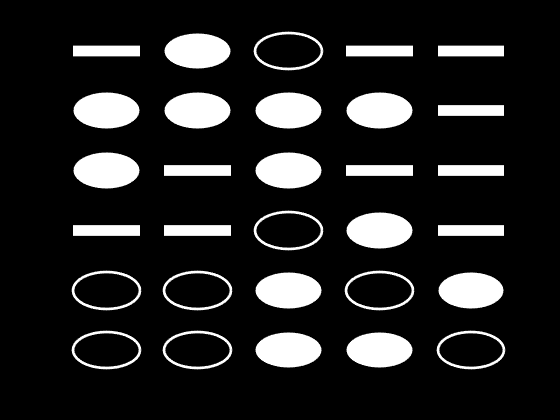


for i =1:r
    for  k=1:c
        num=num+1;
        if  A(i,k)==0 %0用圆环替换
          subplot(r,c,num); plot(x,y,'w-','LineWidth',2);
          set(gcf,'color','black');
          axis off;
        end
        if  A(i,k)==1  %1用圆盘替换
           subplot(r,c,num); fill(x,y,'w-');
           set(gcf,'color','black');
           axis off;
        end
         if  A(i,k)==2  %2用条纹替换
           subplot(r,c,num); plot(z,Z,'w-','LineWidth',8);
           set(gcf,'color','black');
           axis off;
         end
    end
end